# Introduction to Matlab

Greg Teichert

Consulting for Statistics, Computation, and Analytics Research

In this workshop, we will cover some of the basics:

- Variables (scalars, matrices, strings)

- Basic operations and functions

- Loops, conditional statements

- Plotting

- Writing functions

We will also look at a few intermediate topics:

- Symbolic operations

- Integration, differential equations

**Resources **(used in part for the content here):

- [Getting started with Matlab](https://www.mathworks.com/help/matlab/getting-started-with-matlab.html?s_tid=CRUX_lftnav)

## Scalar variables

Define a variable and assign a value with =

a = 3

a = 3

ab = 6

ab = 6

The variable names cannot start with a digit (note the red underline):

%2a = 4

Standard scalar operations and functions are implemented, for example:

a^2 % exponents

ans = 9

a*ab % multiplication

ans = 18

sqrt(ab) % square root

ans = 2.4495

sin(0.3) % trig functions

ans = 0.2955

c = a + ab

c = 9

## Creating  matrices

ones(2,3) % 2 x 3 matrix of ones

ans =      1     1     1
     1     1     1


zeros(4,2) % 4 x 2 matrix of zeros

ans =      0     0
     0     0
     0     0
     0     0


d = [2,3 6;
    2.3 9.1, 8] % define each component

d =     2.0000    3.0000    6.0000
    2.3000    9.1000    8.0000


Commas or space separate items in a row.

Semicolons designate a new row.

## Accessing  elements of matrices

Use parenthese (row, column) to access elements of a matrix.

NOTE: Indices start at 1 (unlike C++ or Python)

A = [3,2;
    1,4]

A =      3     2
     1     4


A(1,2)

ans = 2

Use a colon (:) to access an entire row or column:

A(:,2)

ans =      2
     4


## Matrix operations

A = [3,2;
    1,4]

A =      3     2
     1     4


B = [2 0;
    0 1]

B =      2     0
     0     1


A + B % matrix addition

ans =      5     2
     1     5


A + 10 % a scalar added to a matrix is applied to each element

ans =     13    12
    11    14


A*B % matrix multiplication

ans =      6     2
     2     4



A.*B % elementwise multiplication, using the period (.)

ans =      6     0
     0     4


A' % use the apostrophe (') for transpose

ans =      3     1
     2     4


sin(A) % standard functions apply elementwise

ans =     0.1411    0.9093
    0.8415   -0.7568


inv(A) % inverse of a matrix

ans =     0.4000   -0.2000
   -0.1000    0.3000


## Linear algebra

Additional linear algebra operations:

A = rand(3,3) % random 3x3 matrix

A =     0.7094    0.6797    0.1190
    0.7547    0.6551    0.4984
    0.2760    0.1626    0.9597


b = rand(3,1)

b =     0.3404
    0.5853
    0.2238


inv(A)*b

ans =     7.2997
   -6.9984
   -0.6805


A\b % more efficient than computing the inverse

ans =     7.2997
   -6.9984
   -0.6805


## Exercise

Check if A\b is more efficient than inv(A)*b (try with small and large A).

Use "tic" and "toc" to time, e.g.

tic
for i = 1:100
    x = i+3;
end
toc

Elapsed time is 0.004819 seconds.


A = rand(3)

A =     0.7241    0.0605    0.3228
    0.0659    0.6526    0.5234
    0.2309    0.5281    0.7870


[V,D] = eig(A*A')

ans =     0.6321    0.2562    0.4532
    0.2562    0.7042    0.7718
    0.4532    0.7718    0.9516


ans =     0.6321    0.2562    0.4532
    0.2562    0.7042    0.7718
    0.4532    0.7718    0.9516


[U,S,V] = svd(A)

ans =     0.7241    0.0605    0.3228
    0.0659    0.6526    0.5234
    0.2309    0.5281    0.7870



[Q,R] = qr(A)

ans =     0.7241    0.0605    0.3228
    0.0659    0.6526    0.5234
    0.2309    0.5281    0.7870


## Exercise

Double-check that the singular value, and QR decompositions are correct (i.e. A = USV', A = QR)

## Conditional statements

Some examples:

a = 1;
b = 2;
a <= b % less than or equal to

ans = logical
   1


a > b % greater than

ans = logical
   0


a == b % equal to

ans = logical
   0


a ~= b % not equal to

ans = logical
   1


if (a < b)
    disp('a < b')
elseif (a == b)
    disp('a == b')
else
    disp('a > b')
end

a < b


## Loops

"for" loop:

for i  = 1:3:10 % 1 to 10, jumping by 3
    i
end

i = 1

i = 4

i = 7

i = 10

"while" loop:

x = 0

x = 0

while (x <= 0.5)
    x = rand(1)
end

x = 0.4898

x = 0.4456

x = 0.6463

## Exercise

Which is faster, to do elementwise vector multiplication using a loop, or with the .* notation?

Again, use "tic" and "toc" to time, e.g.

tic

Elapsed time is 0.005841 seconds.


for i = 1:1000
    i+2.3;
end
toc

## Exercise

Write the given "for" loop as a "while" loop:

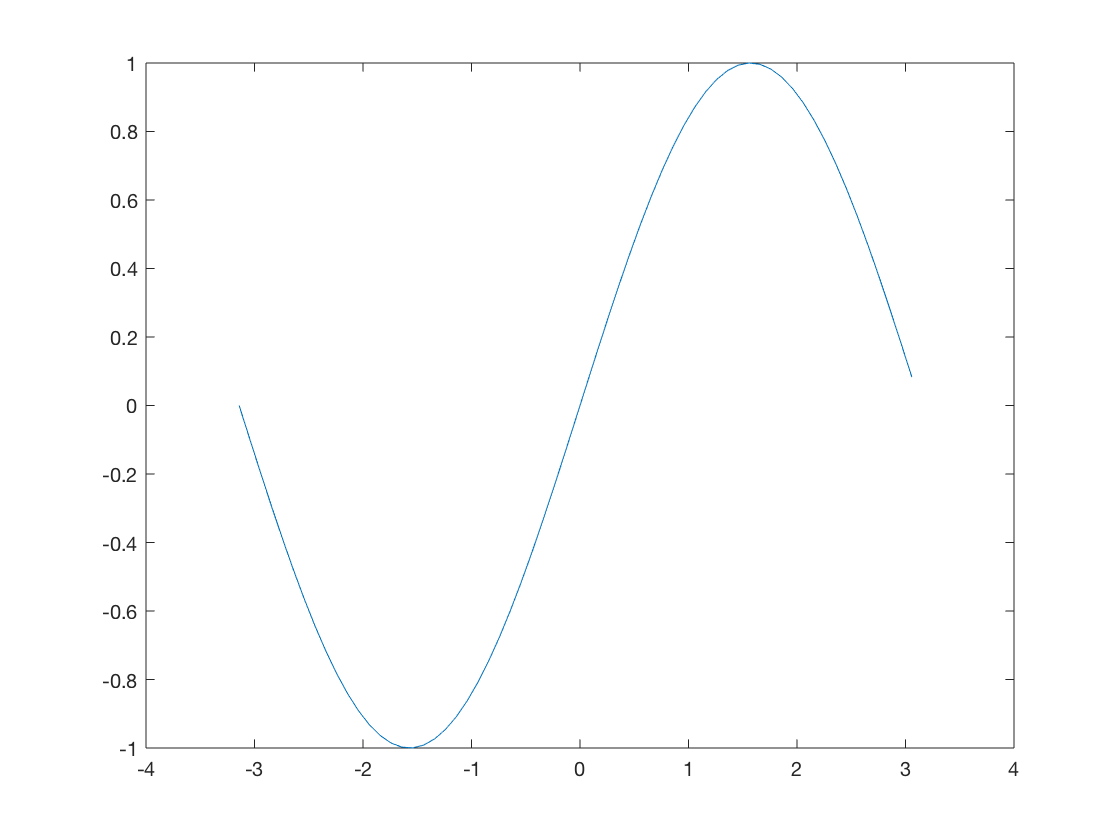

for i  = 1:3:10 % 1 to 10, jumping by 3
    i
end

## Plotting

1D plot:

x = -pi:.1:pi;
y = sin(x);
plot(x,y)

Scatter plot:

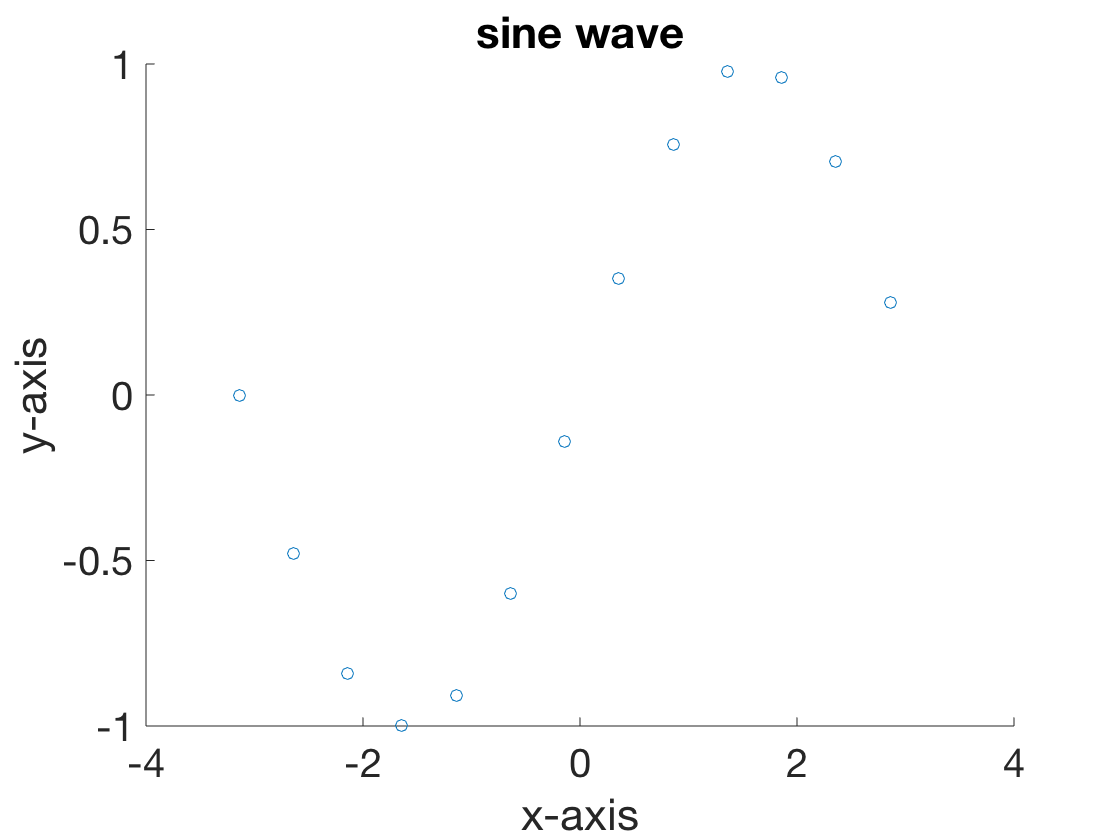

x = -pi:.5:pi;
y = sin(x);
scatter(x,y)
xlabel('x-axis')

ylabel('y-axis')
title('sine wave')
set(gca,'FontSize',20)

Surface plot:

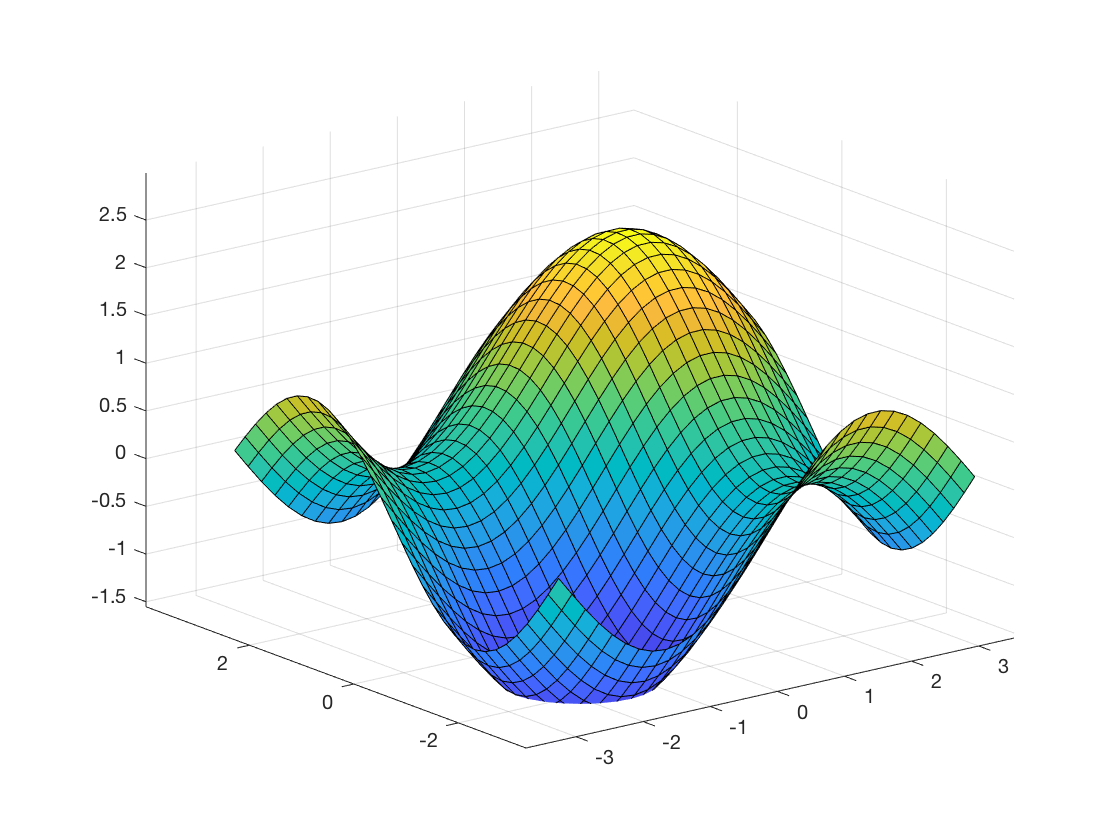

[X,Y] = meshgrid(-pi:.2:pi,-pi:.2:pi);
Z = sin(X) + sin(Y) + 0.01*Y.^2;

surf(X,Y,Z)

Contour plot:

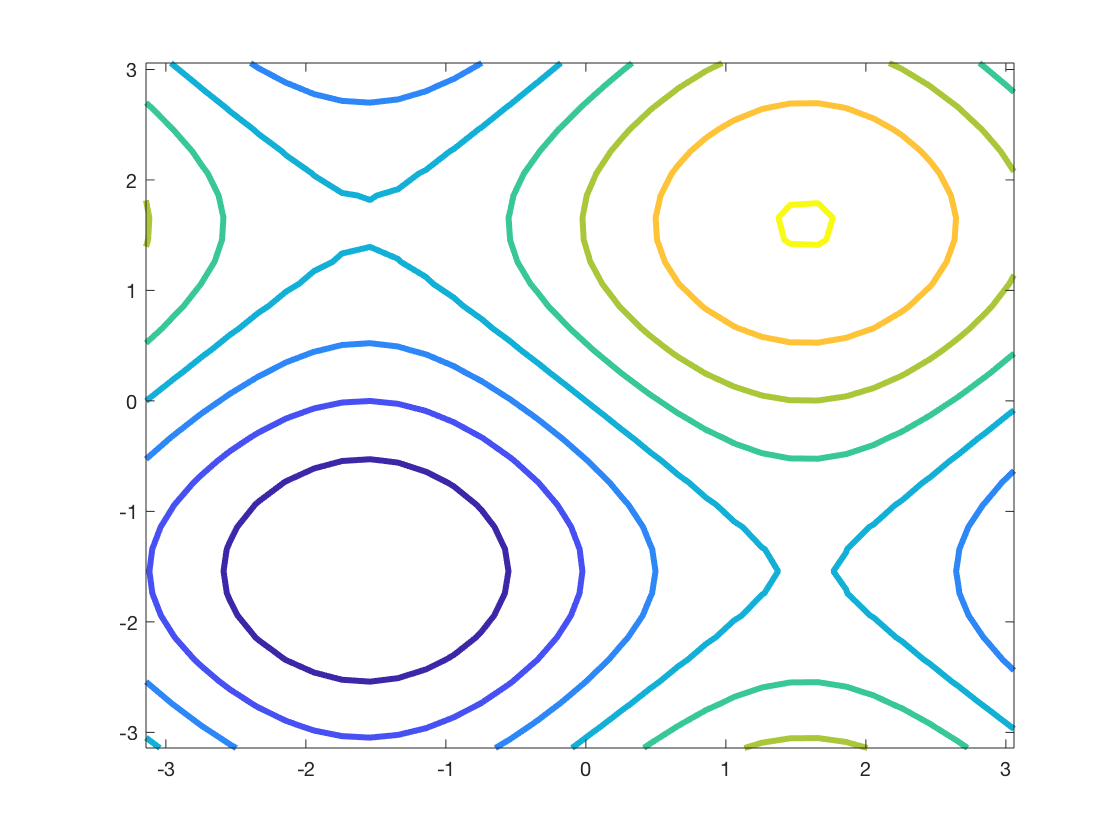

[X,Y] = meshgrid(-pi:.2:pi,-pi:.2:pi);

Z = sin(X) + sin(Y) + 0.01*Y.^2;
contour(X,Y,Z,'LineWidth',3)

Plot as image:

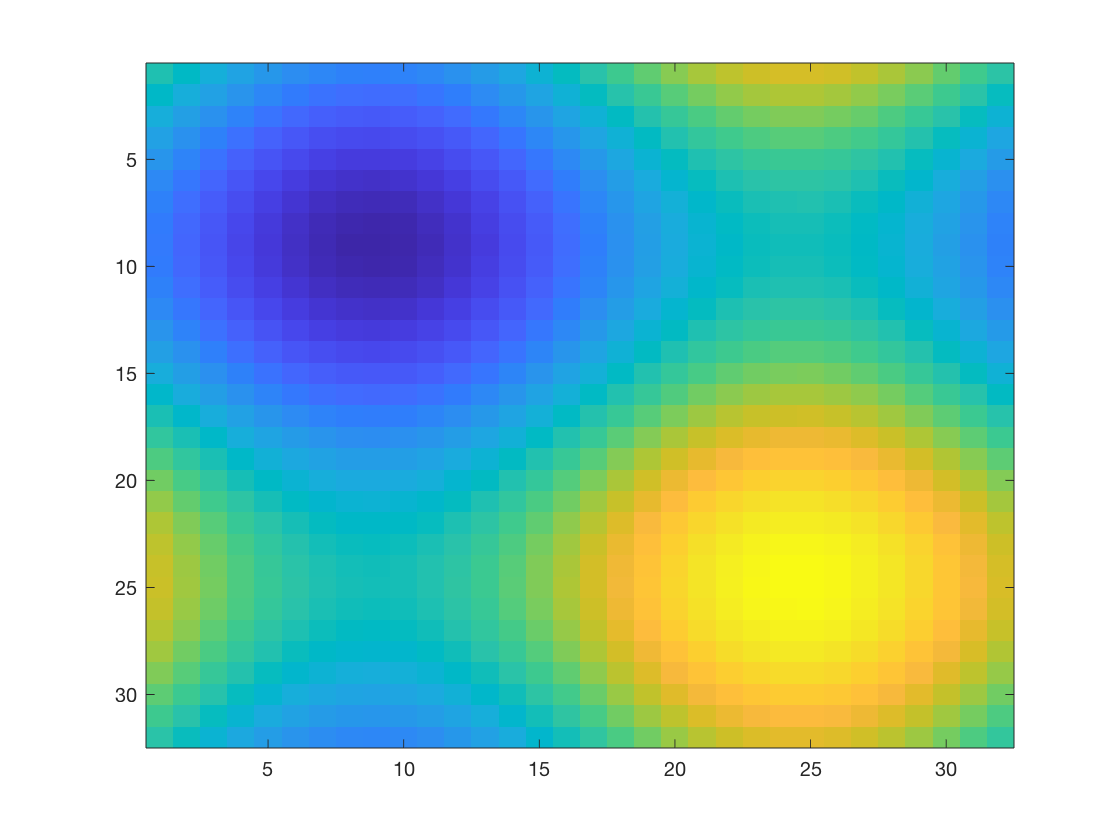

[X,Y] = meshgrid(-pi:.2:pi,-pi:.2:pi);
Z = sin(X) + sin(Y) + 0.01*Y.^2;
imagesc(Z)

## Functions

Anonymous (in-line) functions:

sqr = @(x) x.^2;
sqr(3)

ans = 9

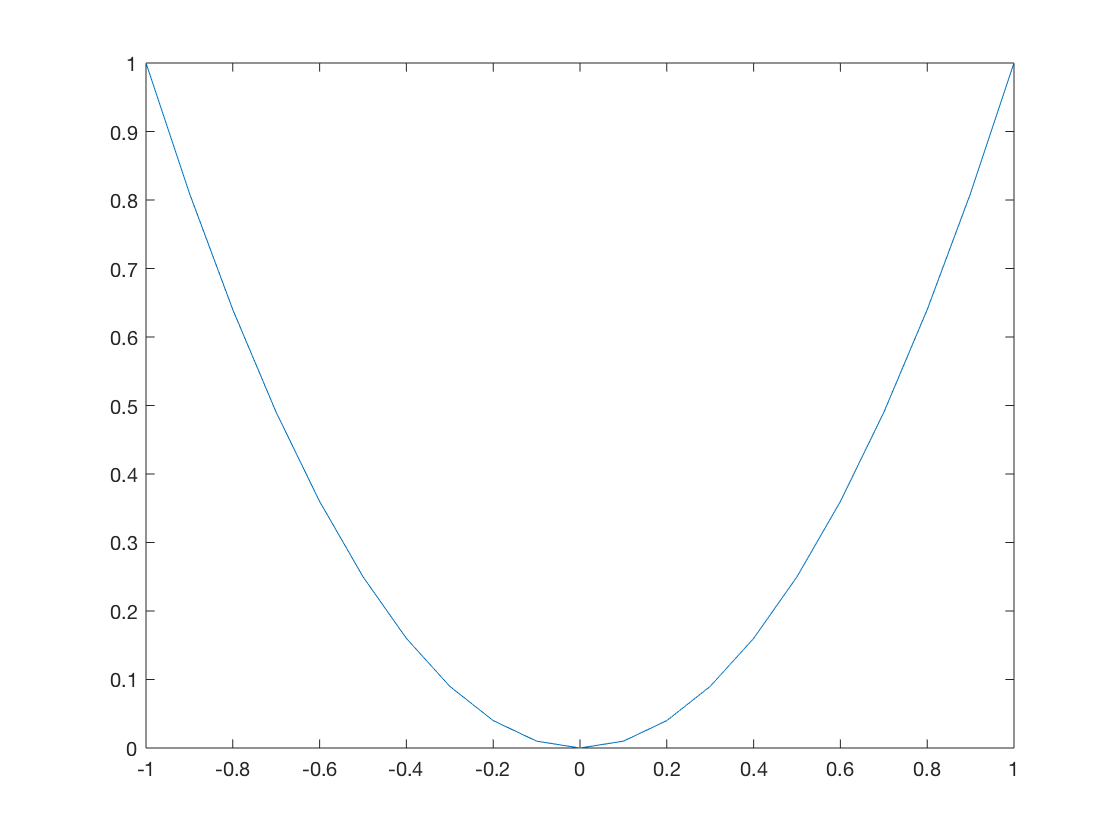

X = -1:.1:1;
plot(X,sqr(X))

Full function:

Function definitions within a file must be at the end of the file:

cube(3)

ans = 27

% function y = cube(x)
% 
%     y = x.^3;
% end

To be called from another file, each function must be in its own file, with the filename the same as the function name.

## Exercise

Write a function for $y = \log(10x^2 + 1)$. Use it to plot the curve for the domain [-2,2].

## Symbolic variables

First, define the symbolic variables

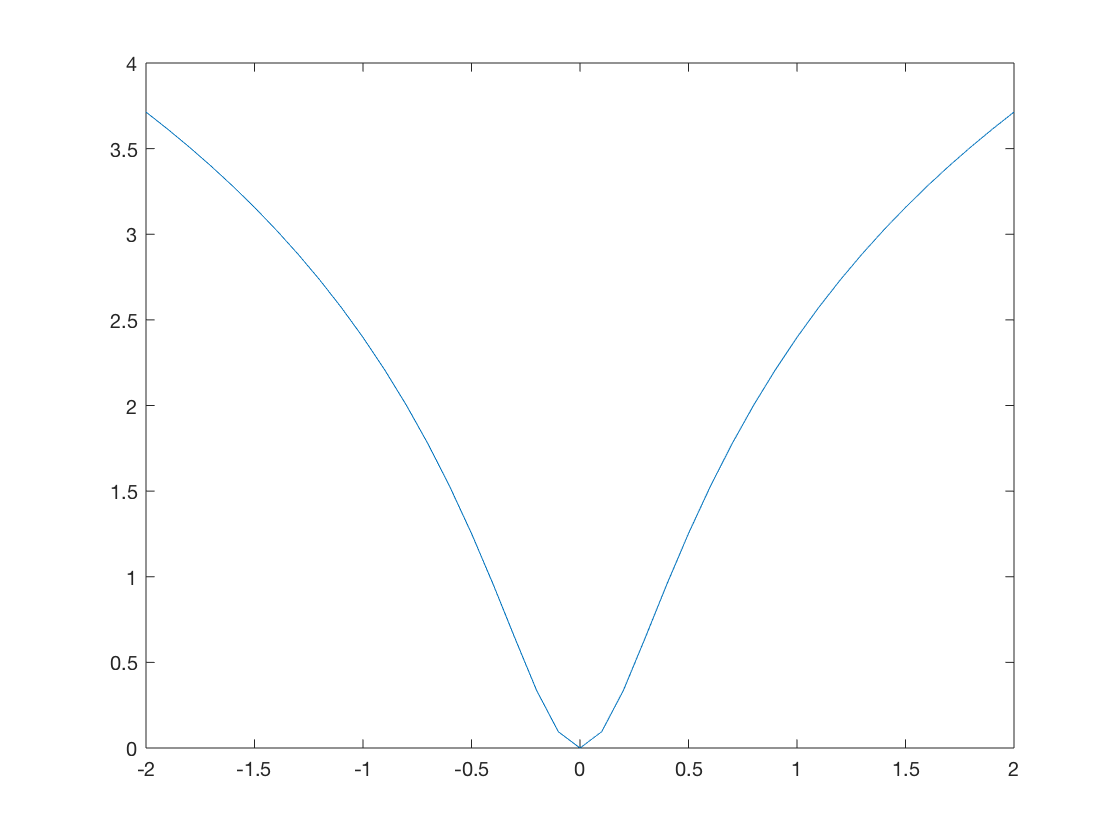

syms a b c x

You can then define expressions based on these symbolic variables:

y = a*x^2 + b*x + c

Subsitute in values for variables:

subs(y,[a,b,c,x],[2,0.3,3,0.2])

$$y = a\,x^{2}+b\,x+c$$

## Symbolic operations

Matlab has a symbolic solver:

solve(y==0)

$$ans = \frac{157}{50}$$

Simplify symbolic expression:

z = a^3*a^2*x/a - b^3*x + x*c*x

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

simplify(z)

## Exercise

Find the intersection of the two curves:

$y_1 = 3x^2 - 4$, $y_2 = -x^2 + x$

$$z = a^{4}\,x-b^{3}\,x+c\,x^{2}$$

Now, find the intersection of:

$y_1 = 3x^2 - 4$, $y_2 = \sin(x) + x$

$$ans = x\,\left(a^{4}-b^{3}+c\,x\right)$$

Plot the lines to verify the result.

## Symbolic calculus

Differentiation:

diff(y,x) % differentiate y with respect to x

$$ans = -0.88376225951495772162614072285116$$

Integration:

int(y,x) % indefinite integral

$$ans = b+2\,a\,x$$

int(y,x,0,1) % definite integral

## Exercise

Verify diff and int (i.e. the derivative of the integral should give the original function)

$$ans = \frac{a\,x^{3}}{3}+\frac{b\,x^{2}}{2}+c\,x$$

## Numerical integration

Since not all functions are analytically integrable, Matlab will perform numerical intregation:

y = @(x) sin(x).*exp(x.^2);

$$ans = \frac{a}{3}+\frac{b}{2}+c$$

integral(y,0,1) % integrate y, from 0 to 1

## Numerical ODE solver

Matlab has multiple ODE solvers; choose the right one for your equations.

ode45 is recommended as the "first one to try". Higher order ODEs should be rewritten as a system of 1st order ODEs.

Example: $t^2y'' + ty' + t^2y = 0$

Rewrite as: $y_1' = y_2$, $y'_2 = -y_2/t - y_1$

Then, ode45 has the syntax: ode45(eqns,[t0,tN],y0)

f = @(t,y) [y(2); -y(2)/t - y(1)];
ode45(f,[.1,10],[1;0])

## Challenge Problem: Plotting the Mandelbrot set

The [Mandelbrot set](https://en.wikipedia.org/wiki/Mandelbrot_set) is the set of all complex numbers $c = a + ib$ such that the sequence $y_{n+1} = y_n^2 + c$, $y_0=0$ does not diverge.

Tasks:

- Write one function that takes y and c as inputs, and returns y^2 + c.

- Write a second function that takes c, n_iter, and tol as inputs.

-     Initialize y=0. 

-     Write a "for" loop from 1 to n_iter.

-     Within the "for" loop, evaluate function 1 with y and c as inputs (y will be updating at each step of the loop).

-     Check if the absolute value of the final y is less than tol (the tolerance). Return 1 if true and 0 otherwise.

- Use meshgrid to create a matrix of a and b values, $a \in [-2,1]$ and $b \in [-1,1]$.

- Create a matrix of complex numbers $c = a + ib$ (use the notation c = a + 1i*b).

- Loop over all components of $c$ and evaluate your second function, using n_iter = 100 and tol = 1000; store the results in a matrix Z.

- Plot Z using imagesc.

ans = 0.7787